# Taller 13 Péndulo simple con fuerza tangencial

introduccion

El presente taller tiene como objetivo principal abordar la resolución numérica de la ecuación de estado no lineal de un péndulo simple con fuerza tangencial. Para lograrlo, utilizaremos el método numérico de Runge-Kutta, implementado a través de la función ode45 de MATLAB. Este enfoque nos permitirá obtener soluciones precisas y eficientes para el comportamiento dinámico del sistema.

El péndulo simple con fuerza tangencial es un sistema mecánico de gran interés debido a su comportamiento no lineal, lo cual lo convierte en un caso de estudio relevante en la teoría de sistemas dinámicos. A lo largo de este taller, exploraremos la respuesta temporal y el retrato de fase del sistema al variar diferentes parámetros, lo que nos brindará una comprensión más profunda de su comportamiento y nos permitirá realizar análisis cualitativos y cuantitativos.

Mediante el uso de un archivo Live Script en MATLAB, podremos documentar y visualizar de manera interactiva los resultados obtenidos, lo que facilitará la interpretación de los mismos. Este enfoque proporciona una herramienta valiosa para analizar el efecto de diferentes configuraciones y condiciones iniciales en el sistema, permitiendo así un estudio exhaustivo de su comportamiento dinámico.

A lo largo de este taller, se abordarán los fundamentos teóricos del péndulo simple con fuerza tangencial, se describirá la metodología de resolución numérica a través del método de Runge-Kutta implementado en ode45, y se presentarán las interpretaciones de los resultados obtenidos al manipular los parámetros del sistema.

- Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

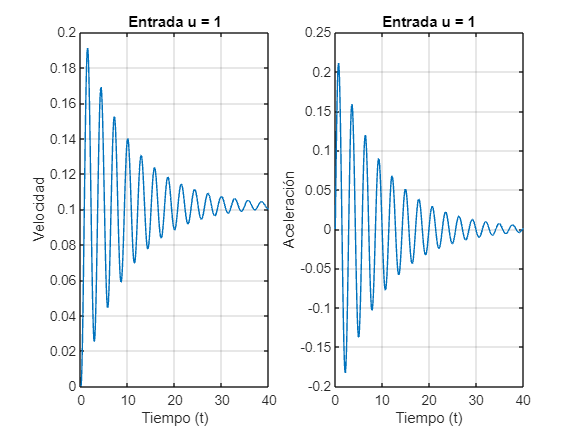

syms variable1(t) variable2(t)

m = 1; g = 9.8; l = 2; u = 1; f = 0.2; 

ecuacion1 = variable2;
ecuacion2 = (-g/l)*sin(variable1)-(f/m)*variable2+(u/(m*l));

F = odeFunction([ecuacion1 ecuacion2],[variable1 variable2]);

h1 = 0.01;
tmin = 0;
tmax = 100;
tspan = tmin:h1:tmax;

condiciones_iniciales = [0,0];

[t, sol] = ode45(F,tspan,condiciones_iniciales);

variable1 = sol(:,1); variable2 = sol(:,2);

tlimite = 40;

Fig1 = figure;

subplot(1,2,1)
    plot(t,variable1)
    grid on
    title ('Entrada u = 1')
    xlim([0 tlimite])
    xlabel('Tiempo (t)')
    ylabel('Velocidad')

subplot(1,2,2)
    plot(t,variable2)
    grid on
    title ('Entrada u = 1')
    xlim([0 tlimite])
    xlabel('Tiempo (t)')
    ylabel('Aceleración')

Respuesta a valor máximo de la entrada el sistema rotará indefinidamente

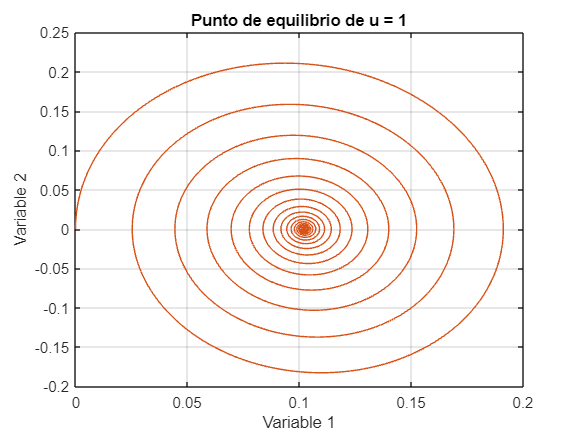

Fig2 = figure;

subplot(1,1,1)  
    plot(variable1,variable2)
    hold on 
    plot(variable1,variable2)
    title ('Punto de equilibrio de u = 1')
    xlabel('Variable 1')
    ylabel('Variable 2')
    grid on

Entrada u=7.6

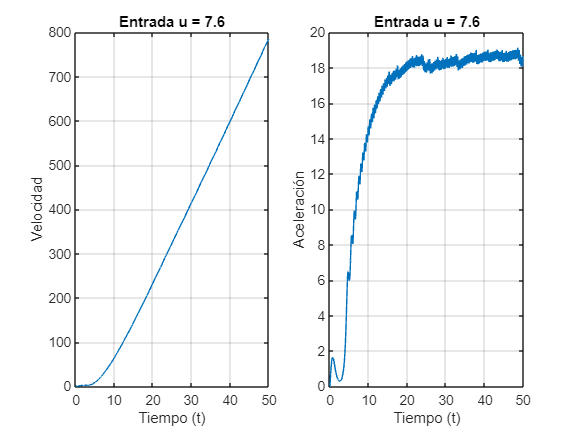

    syms variable1(t) variable2(t)

m = 1; g = 9.8; l = 2; u = 7.6 ; f = 0.2;

ecuacion1 = variable2;
ecuacion2 = (-g/l)*sin(variable1)-(f/m)*variable2+(u/(m*l));

F = odeFunction([ecuacion1 ecuacion2],[variable1 variable2]);

h1 = 0.01;
tmin = 0;
tmax = 100;
tspan = tmin:h1:tmax;

condiciones_iniciales = [0,0];

[t, sol] = ode45(F,tspan,condiciones_iniciales);

variable1 = sol(:,1); variable2 = sol(:,2);

tlimite = 50;

Fig3 = figure;

subplot(1,2,1)
    plot(t,variable1)
    grid on
    title ('Entrada u = 7.6')
    xlim([0 tlimite])
    xlabel('Tiempo (t)')
    ylabel('Velocidad')

subplot(1,2,2)
    plot(t,variable2)
    title ('Entrada u = 7.6')
    xlim([0 tlimite])
    grid on
    xlabel('Tiempo (t)')
    ylabel('Aceleración')

Punto de equilibrio

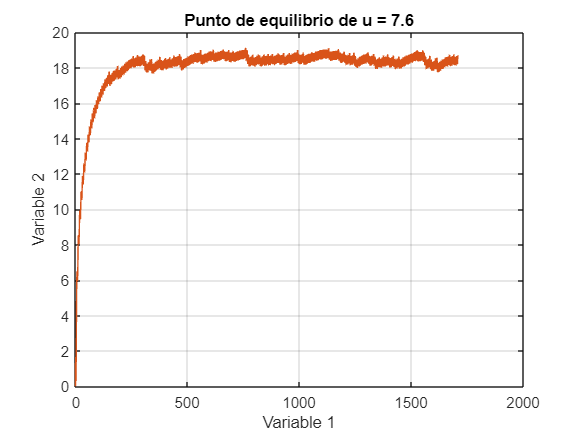

    Fig4 = figure;

subplot(1,1,1)
    plot(variable1,variable2)
    hold on 
    plot(variable1,variable2)
    title ('Punto de equilibrio de u = 7.6')
    xlabel('Variable 1')
    ylabel('Variable 2')
    grid on

Se aborda el problema utilizando métodos numéricos y se grafican las soluciones temporales para una entrada "u = 1". Inicialmente, se observa que cuando la entrada es de magnitud moderada (u = 1), el sistema tiende a equilibrarse en torno a los puntos de equilibrio, siendo estos cercanos a 0 para la aceleración y aproximadamente 0.1 para la velocidad.

Esta situación puede entenderse como la tendencia del péndulo a regresar a su posición de equilibrio inicial después de ser perturbado, lo cual es característico de sistemas no lineales. Es importante destacar que el comportamiento del sistema puede variar significativamente según las condiciones iniciales y la influencia de factores externos, como la presencia de una corriente de aire representada por "u".

Cuando se incrementa la magnitud de la entrada "u", se observa un cambio en el comportamiento del sistema. A medida que "u" aumenta, el péndulo comienza a rotar indefinidamente, indicando una transición de oscilación a rotación continua. Esta transición se aprecia entre los valores de "u = 7" y "u = 8".

Tras analizar detalladamente las gráficas y el comportamiento del sistema, se determina que el valor crítico que marca la transición a la rotación indefinida es "u = 7.6". Para valores de "u" menores a este umbral, el péndulo oscila alrededor de su punto de equilibrio, mientras que para valores mayores, el péndulo gira indefinidamente en círculos.

- 2 Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

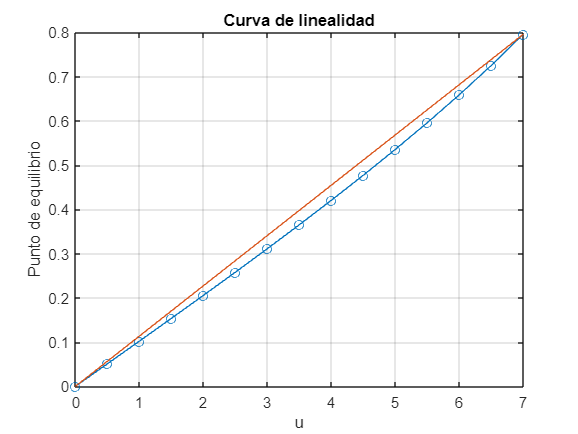

syms theta(t) omega(t)

m = 1; g = 9.8; L = 2; f = 0.2; 

eq1 = omega;

Input = 0:0.5:7;

tspan = 0:0.1:100;

ci = [0 0];

thetaL = zeros(1, length(Input));

for i = 1:length(Input)
    u = Input(i);
    eq2 = -(g/L)*sin(theta)-(f/m)*omega+(u/(m*L));
    fun = odeFunction([eq1 eq2],[theta omega]);
    [~,sol] = ode45(fun,tspan,ci);
    thetaL(i) = sol(end, 1);
end

figure

plot(Input,thetaL,'o-')

hold on

plot([0 Input(end)],[0 thetaL(end)])

title ('Curva de linealidad')

xlabel('u')

ylabel('Punto de equilibrio')

grid on

El análisis del comportamiento del péndulo simple no lineal, bajo la influencia de una fuerza tangencial variable (`u`), revela un cambio significativo en el punto de equilibrio del sistema en función de la entrada aplicada. Al introducir fricción y una fuerza externa, se observa una curva sutil en la gráfica de la curva de linealidad. Esta curva sugiere una respuesta no lineal del sistema, con una ligera deformación hacia arriba en forma convexa. Para determinar con precisión el valor en el que se estabiliza el péndulo en relación con la entrada, se debe asegurar que el rango de valores de `u` no supere el valor máximo previamente calculado de 7.6. El intervalo de valores de `Input` está definido de 0 a 7, lo que concuerda con el límite crítico antes de que el sistema pase de un estado oscilatorio a un estado rotatorio continuo. Este análisis demuestra la importancia de comprender y controlar los parámetros de entrada en sistemas no lineales para garantizar un comportamiento estable y seguro.

- 3 Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

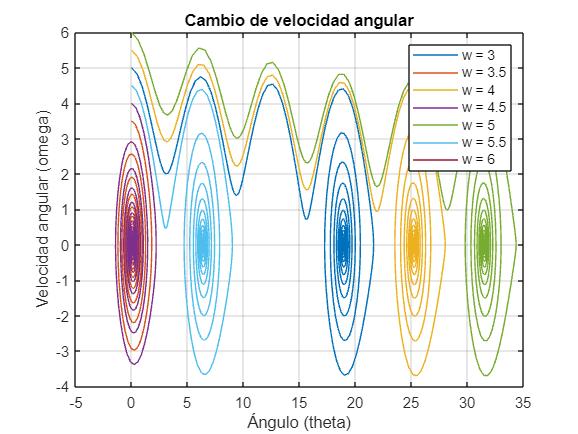

syms theta(t) omega(t)

m = 1; 
g = 9.8; 
l = 2; 
f = 0.2;  
u = 1;

eq1 = omega;
eq2 = -(g/l)*sin(theta)-(f/m)*omega+(u/(m*l));

ode_fun = odeFunction([eq1 eq2],[theta omega]);

initial_omegas = 3:0.5:6;

time_span = 0:0.1:100;

figure

for i = 1:length(initial_omegas)
    initial_conditions = [0 initial_omegas(i)];
    
    [~,sol] = ode45(ode_fun,time_span,initial_conditions);
    
    plot(sol(:,1),sol(:,2))
    plot(0, initial_omegas(i))
    
    hold on
end

title('Cambio de velocidad angular')
xlabel('Ángulo (theta)')
ylabel('Velocidad angular (omega)')

legend({'w = 3','w = 3.5', 'w = 4','w = 4.5', 'w = 5', 'w = 5.5', 'w = 6'})

grid on

El retrato de fase proporciona una visualización completa del comportamiento dinámico del péndulo simple no lineal. Cada ciclo de las líneas de color en la gráfica representa una vuelta completa, lo que permite identificar puntos específicos de estabilidad y evaluar la frecuencia angular inicial necesaria para lograr diferentes cantidades de vueltas. se nota que a mayores frecuencias angulares, el péndulo completa un mayor número de vueltas. Este análisis permite comprender cómo la velocidad inicial del péndulo influye en el número de vueltas que realizará y cómo las trayectorias eventualmente convergen hacia los puntos de equilibrio estables.

- 4 Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

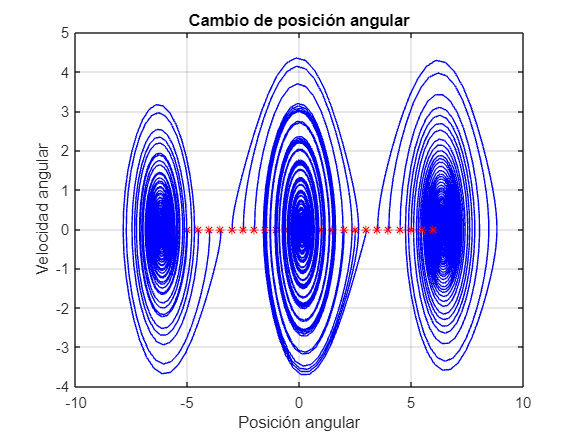

syms theta(t) omega(t)
m = 1; g = 9.8; L = 2; friction = 0.2; input_force = 1;
eq1 = omega;
eq2 = -(g/L)*sin(theta)-(friction/m)*omega+(input_force/(m*L));
fun = odeFunction([eq1 eq2],[theta omega]);
initial_angles = -6:0.5:6;
time_span = 0:0.1:100;
figure
for i = 1:length(initial_angles)
    initial_conditions = [initial_angles(i) 0];
    [~,sol] = ode45(fun,time_span,initial_conditions);
    plot(sol(:,1),sol(:,2),'b')
    plot(initial_angles(i), 0,'*r')
    hold on
end
title('Cambio de posición angular')
xlabel('Posición angular')
ylabel('Velocidad angular')
hold off
grid on

Aqui se simular el movimiento de un péndulo simple, representando en diversas trayectorias que parten de diferentes posiciones angulares iniciales, abarcando un rango desde aproximadamente -8 hasta 9 radianes, con una velocidad angular inicial de 0. A medida que transcurre el tiempo, se observa que el péndulo tiende a estabilizarse hacia tres puntos de equilibrio específicos: (-6 , 0), (0 , 0) y (6.2 , 0). Estos puntos indican que el péndulo puede reposar en distintas posiciones angulares sin experimentar movimiento angular adicional, lo cual es consistente con el comportamiento esperado de un péndulo simple en un sistema sin pérdida de energía.

- 5 Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

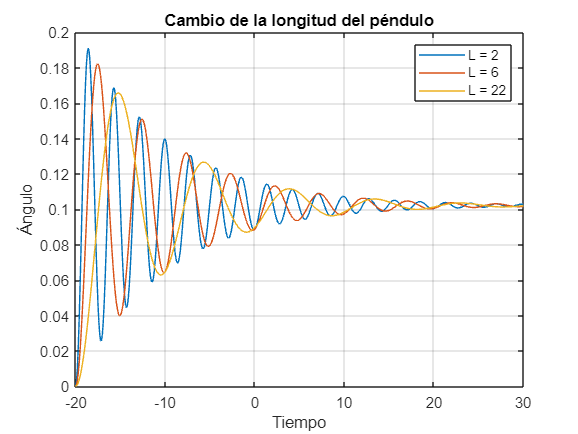

syms angle(t) angular_velocity(t)
m = 1; g = 9.8; f = 0.2; u = 1;
L_values = [2 6 22];
for i = 1:length(L_values)
    l = L_values(i);
    eq1 = angular_velocity;
    eq2 = -(g/l) * sin(angle) - f/m * angular_velocity + u/(m*l);
    ode = odeFunction([eq1 eq2], [angle angular_velocity]);
    t_min = -20;
    t_max = 30;
    step = 0.1;
    t_interval = t_min:step:t_max;
    initial_conditions = [0 0];
    [t, sol] = ode45(ode, t_interval, initial_conditions);
    plot(t, sol(:,1)), 
    hold on
end
title('Cambio de la longitud del péndulo')
xlabel("Tiempo")
ylabel('Ángulo')
hold off
legend('L = 2', 'L = 6', 'L = 22')
grid on

Al simular el comportamiento de tres péndulos simples con longitudes diferentes (2, 6 y 22 unidades), representando gráficamente la variación del ángulo en función del tiempo. Las gráficas confirman que la longitud del péndulo afecta la velocidad y amplitud de las oscilaciones, observándose que péndulos más largos tienen oscilaciones más lentas y suaves, mientras que los más cortos oscilan de manera más rápida y agitada. A pesar de estas diferencias, todos los péndulos alcanzan un estado de equilibrio en aproximadamente 0.12 unidades de tiempo, demostrando un comportamiento universal independiente de la longitud del péndulo.

- 6 Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

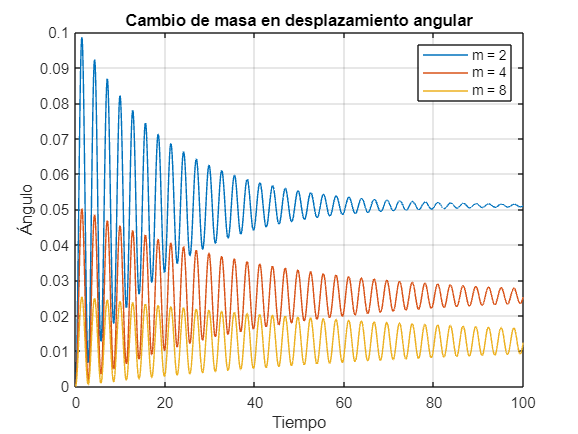

m_values = [2 4 8];  
g = 9.8;  
l = 2;  
f = 0.2; 
u = 1;

for i = 1:numel(m_values)
    syms theta(t) omega(t)
    
    F1 =  omega; 
    F2 = -(g/l)*sin(theta) - (f/m_values(i))*omega + u/(m_values(i)*l);
    
    F = odeFunction([F1 F2],[theta omega]);
    
    h = 0.01;
    t_min = 0;
    t_max = 100;
    
    t_span = t_min:h:t_max;
    initial_conditions = [0 0];
    
    [t, sol] = ode45(F, t_span, initial_conditions);
    
    theta_values = sol(:,1);
    
    plot(t, theta_values)
    xlabel("Tiempo")
    ylabel("Ángulo")
    hold on
end

legend({'m = 2','m = 4', 'm = 8'})
title('Cambio de masa en desplazamiento angular')
hold off
grid on

La simulación de tres péndulos con masas distintas (2, 4 y 8 unidades) y la graficacion del cambio del ángulo en función del tiempo. Muestran que a medida que aumenta la masa, las oscilaciones se vuelven más lentas y suaves, lo que se refleja en las gráficas al mostrar movimientos menos bruscos. Por otro lado, para masas menores, las oscilaciones son más rápidas y agitadas, lo que se evidencia por una mayor cantidad de oscilaciones en un intervalo de tiempo. Es interesante notar que, independientemente de la masa, los ángulos de equilibrio son diferentes, aproximadamente 0.061 para masa de 2, 0.025 para masa de 4 y 0.014 para masa de 8. Además, el sistema con mayor masa tiende a tener oscilaciones más reducidas pero que persisten en el intervalo de tiempo, mientras que el péndulo con menor masa se estabiliza hacia su punto de equilibrio en un tiempo menor que las demás masas.

- 7 Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

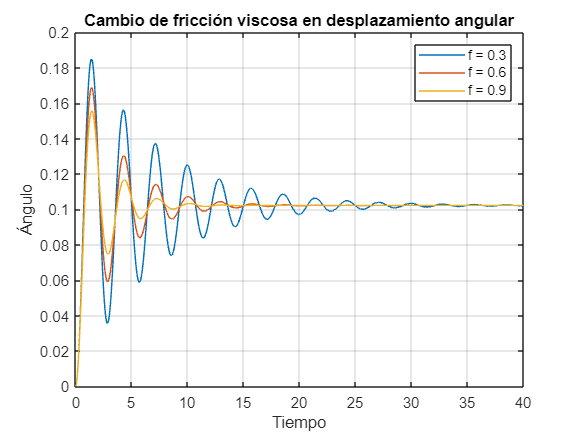

clear all

m = 1;  
g = 9.8;  
l = 2;  
f_values = [0.3 0.6 0.9]; 
u = 1;

for i = 1:numel(f_values)
    syms X1(t) X2(t)
    
    F1 = X2; 
    F2 = -(g/l)*sin(X1) - (f_values(i)/m)*X2 + u/(m*l);
    
    F = odeFunction([F1 F2],[X1 X2]);
    
    h = 0.01;
    tmin = 0;
    tmax = 40;
    tspan = tmin:h:tmax;
    
    ci = [0 0];
    
    [t, sol] = ode45(F, tspan, ci);
    theta = sol(:,1);
    
    plot(t, theta)
    xlabel("Tiempo")
    ylabel("Ángulo")
    hold on
end

title('Cambio de fricción viscosa en desplazamiento angular')

legend({'f = 0.3','f = 0.6','f = 0.9'})

hold off
grid on

Al realizar diferentes simulaciones de un péndulo simple con diferentes coeficientes de fricción (0.3, 0.6 y 0.9). Observamos que a medida que aumenta el coeficiente de fricción, las oscilaciones del péndulo se vuelven más amortiguadas y el péndulo se estabiliza más rápidamente hacia su posición de equilibrio. Esto se debe a que la fricción actúa como una resistencia al movimiento, disipando la energía del sistema. En la gráfica, podemos ver que el péndulo con un coeficiente de fricción de 0.9 muestra las oscilaciones más atenuadas y se estabiliza más rápidamente en comparación con los otros dos casos.

- 9 Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

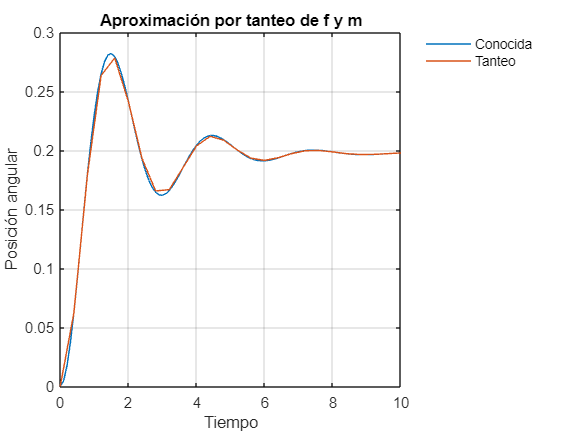

Time    = [0 0.4000 0.8000 1.2000 1.6000 2.0000 2.4000 2.8000 3.2000 3.6000 4.0000 4.4000 4.8000 5.2000 5.6000 6.0000 6.4000 6.8000 7.2000 7.6000 8.0000 8.4000 8.8000 9.2000 9.6000 10.0000];
Angle   = [0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];
syms Theta(t) Omega(t)
mass    = 0.52; 
gravity = 9.8; 
length  = 2; 
damping = 1; 
friction= 0.6; 

eq1 = Omega;
eq2 = (-gravity/length)*sin(Theta)-(friction/mass)*Omega+(damping/(mass*length));
odeFunc = odeFunction([eq1 eq2],[Theta Omega]);

timeSpan = 0:0.1:10;
initialConditions = [0, 0];
[~, solution] = ode45(odeFunc, timeSpan, initialConditions);

figure
plot(timeSpan, solution(:,1))
hold on
plot(Time, Angle)
legend({'Conocida', 'Tanteo'}, 'location', 'bestoutside', 'box', 'off');
title('Aproximación por tanteo de f y m')
xlabel('Tiempo')
ylabel('Posición angular')
grid on
hold off

Mediante el método de tanteo, se ajustan los valores de m y f para que el comportamiento del sistema se asemeje lo más posible al conocido. En este caso, se utilizaron m = 0.52 y f = 0.6 como estimaciones iniciales, mientras que g = 9.8, l = 2 y u = 1 se mantienen constantes. Al implementar estos ajustes, se logra una notable similitud entre las tendencias de posición en cada instante de tiempo, lo que indica una aproximación exitosa del sistema.

## concluciones 

- Con base en las actividades realizadas, se pudo observar que al modificar los parámetros y condiciones iniciales del sistema, se obtuvieron respuestas temporales y retratos de fase distintos. La graficación fue esencial para visualizar patrones y tendencias que no son fácilmente perceptibles a simple vista, proporcionando valiosa información sobre el comportamiento del péndulo en diferentes escenarios.

- La selección de límites de tiempo en las gráficas (tmin, tmax, tspan) fue crucial para simular y analizar adecuadamente el comportamiento del sistema en el intervalo deseado. Además, la consideración de las condiciones de montaje del péndulo fue fundamental para comprender y interpretar los resultados obtenidos.

- El uso de métodos numéricos, como el método de Runge-Kutta implementado en la función ode45 de MATLAB, demostró ser una herramienta poderosa para modelar y analizar sistemas físicos complejos, como el péndulo simple con fuerza tangencial. Esto permitió encontrar relaciones entre variables y hallar equilibrios convenientes y tendencias esperadas.

- El análisis de los resultados también resalta la importancia de comprender el contexto del experimento, como el efecto de la longitud de la cuerda, la masa y la fricción en el desplazamiento angular del péndulo. Por ejemplo, se observó que una cuerda más larga resulta en oscilaciones más lentas y menos cambios bruscos en las gráficas.

- En resumen, este taller proporcionó una experiencia valiosa en la aplicación de métodos numéricos para resolver y analizar sistemas físicos, demostrando la relevancia y aplicabilidad de las ecuaciones diferenciales en situaciones reales. El conocimiento adquirido no solo se limita al péndulo, sino que se extiende a una amplia gama de aplicaciones en diversos campos de la ingeniería y la ciencia.